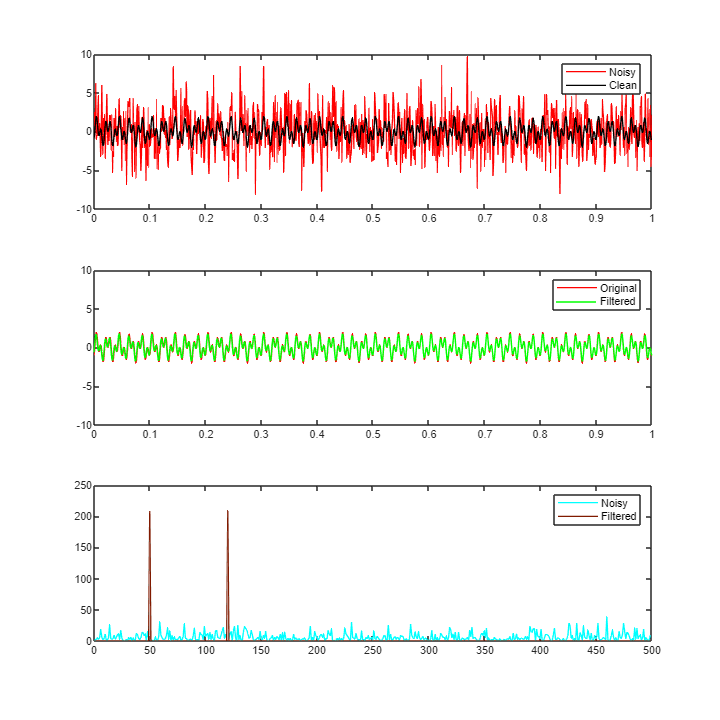

clear all, close all,clc
%%Create a simple signal with two frequencies(like when two signal were interference)
dt = 0.001; %delta t
t =0:dt:1; %step
fclean = sin(2*pi*50*t)-cos(2*pi*120*t); % Sum of two frequencise
f=fclean +2.5*randn(size(t)); % Add some noise
%--------showing part%
figure; set(gcf,"Position",[1500 200 720 720])
subplot(3,1,1)
plot(t,f,'r','LineWidth',1), hold on
plot(t,fclean,'k','LineWidth',1)
li =legend('Noisy','Clean'); set(li,'FontSize',8)
ylim([-10 10]); set(gca,'FontSize',8)

%%Compute the Fast Fourier Tranform
n = length(t);
fhat = fft(f,n);
PSD = fhat.*conj(fhat)/n;
freq = 1/(dt*n)*(0:n);
L = 1:floor(n/2);

subplot(3,1,3); set(gca,'FontSize',8)
plot(freq(L),PSD(L),'c','LineWidth',1), hold on
set(gca,'FontSize',8)

%%Use the PSD to filter out noise
indices = PSD>100;
PSDclean = PSD.*indices;
fhat = indices.*fhat;
ffilt = ifft(fhat);

plot(freq(L),PSDclean(L),'-','Color',[.5 .1 0],'LineWidth',1)
li = legend('Noisy','Filtered');set(li,'FontSize',8)

subplot(3,1,2);set(gca,'FontSize',8)
plot(t,fclean,'r','LineWidth',1), hold on
plot(t,ffilt,'g','LineWidth',.75)
li = legend('Original','Filtered'); set(li,'FontSize',8)
ylim([-10 10]); set(gca,'FontSize',8)